# Gabriel Colangelo

clear
close all
clc

## Problem 1- a)


$$\underline{Find}: \theta^* \ \text{in the original orbit where the maneuver should take place}, \bar{r}, \gamma^-, \bar{v}^-$$


% Earth Parameters
mu_earth    = 398600.4415;
R_earth     = 6378.1363;

% Old orbit parameters
rp          = 1.5*R_earth;          % [km]
ra          = 8*R_earth;            % [km]

% Semi major axis of old orbit
a           = (ra + rp)/2;          % [km]

% Eccentricity of old orbit
e           = ra/a - 1;

% Semi-latus rectum of old orbit
p           = a*(1 - e^2);          % [km]

% New orbit parameters
rp_new      = 2*R_earth;            % [km]
ra_new      = 6*R_earth;            % [km]

% Desired change in arguement of periapsis
delta_AOP   = 90;                   % [deg]

% Semi major axis of new orbit
a_new       = (ra_new + rp_new)/2; % [km]

% Eccentricity of old orbit
e_new       = ra_new/a_new - 1;

% Semi-latus rectum of old orbit
p_new       = a_new*(1 - e_new^2); % [km]

% Run optimization quietly
opts        = optimoptions('fsolve','Display', 'off');

% Run nonlinear solver - solution 1
x           = fsolve(@(x) OrbitManeuver(x, p_new, e_new, p, e, delta_AOP),[0,0],opts);

% Extract solution
ta_1        = x(2);
ta_new_1    = x(1);
fprintf('The true anomaly in the original orbit for the first option is %.3f deg',ta_1)

The true anomaly in the original orbit for the first option is 69.727 deg

% Run nonlinear solver - solution 2
x           = fsolve(@(x) OrbitManeuver(x, p_new, e_new, p, e, delta_AOP),[180,180],opts);

% Extract solution
ta_2        = x(2);
ta_new_2    = x(1);
fprintf('The true anomaly in the original orbit for the second option is %.3f deg',ta_2)

The true anomaly in the original orbit for the second option is 227.058 deg


$$a  = \frac{r_a + r_p}{2} \\ 
e  = \frac{r_a}{a} -1 \\
p = a(1-e^2) \\
r = \frac{p}{1 - e\cos{\theta^*}} \\
r = r_N  =  \frac{p}{1 - e\cos{\theta^*}} =  \frac{p_N}{1 - e_N\cos{\theta_N^*}} \\
\Delta\omega = \theta^* - \theta^*_N \\
\\
\frac{p}{1 - e\cos{\theta^*}} -  \frac{p_N}{1 - e_N\cos{\theta_N^*}} = 0 \\
\theta^* - \theta^*_N  - \Delta\omega = 0 \\

\\
\theta^*_1  = 69.7 \ [deg] \\
 \theta^*_{N,1} = -20.3 \ [deg] \\

\theta^*_2  = 227.0 \ [deg] \\
 \theta^*_{N,2} = 137.1 \ [deg] \\

$$


% Calculate specific energy of each orbit
energy      = -mu_earth/(2*a);
energy_new  = -mu_earth/(2*a_new);

% Calculate specific angular momentum of each orbit
h           = sqrt(mu_earth*p);
h_new       = sqrt(mu_earth*p_new);

% Get orbital radius at each possible maneuver point
r_1         = p/(1 + e*cosd(ta_1));
r_2         = p/(1 + e*cosd(ta_2));

% Get original velocity at both maneuver point options
v_1         = sqrt(2*(energy + mu_earth/r_1));
v_2         = sqrt(2*(energy + mu_earth/r_2));

% Get new velocity at both maneuver point options
v_new_1     = sqrt(2*(energy_new + mu_earth/r_1));
v_new_2     = sqrt(2*(energy_new + mu_earth/r_2));

% Get original FPA at both maneuver point options
gamma_1     = acosd(h/(r_1*v_1));           % ta = 69.7, ascending (+)
gamma_2     = -acosd(h/(r_2*v_2));          % ta = 227 = -132, descending (-)

% Get new FPA at both maneuver point options
gamma_new_1 = -acosd(h_new/(r_1*v_new_1));  % ta = -20.3, descending (-)
gamma_new_2 = acosd(h_new/(r_2*v_new_2));   % ta = 137, ascending (+)

% Calculate deltaV magnitude
deltaV_1    = sqrt(v_new_1^2 + v_1^2 - 2*v_1*v_new_1*cosd(gamma_new_1 - gamma_1));
deltaV_2    = sqrt(v_new_2^2 + v_2^2 - 2*v_2*v_new_2*cosd(gamma_new_2 - gamma_2));

if deltaV_1 < deltaV_2
    r           = r_1;
    v           = v_1;
    gamma       = gamma_1;
    ta          = ta_1;
    deltaV      = deltaV_1;
    v_new       = v_new_1;
    gamma_new   = gamma_new_1;
    ta_new      = ta_new_1;
else 
    r           = r_2;
    v           = v_2;
    gamma       = gamma_2;
    ta          = ta_2;
    deltaV      = deltaV_2;
    v_new       = v_new_2;
    gamma_new   = gamma_new_2;
    ta_new      = ta_new_2;
end

% Define original velocity vector in orbit frame
v_R        = [v*sind(gamma), v*cosd(gamma)]';

fprintf(['The minimum delta V is %.3f km/s. \n' ,...
'The maneuver should take place at a true anomaly of %.3f deg in the original orbit. \n', ...
'The orbital radius at the maneuver point is %.2f Earth Radii. \n', ...
'The flight path angle prior to the maneuver is %.3f deg'], deltaV,ta,r/R_earth,gamma)

The minimum delta V is 4.021 km/s. 
The maneuver should take place at a true anomaly of 69.727 deg in the original orbit. 
The orbital radius at the maneuver point is 2.04 Earth Radii. 
The flight path angle prior to the maneuver is 27.421 deg


$$h = \sqrt{\mu p} = rv\cos{\gamma} \\
\epsilon = \frac{-\mu}{2a} = \frac{v^2}{2} - \frac{\mu}{r} \\
v = \sqrt{2(\epsilon + \frac{\mu}{r})} \\
r = \frac{p}{1 - e\cos{\theta^*}} \\
\Delta v = (v^{-2} + v^{+2} - 2v^-v^+\cos{\Delta \gamma})^{1/2} \\
\\
\textbf{At the maneuver point: } \  \theta^* = 69.7 \ [deg] \\

\gamma^- = \cos^{-1}{\frac{h}{rv^-}} = 27.4 \ [deg] \\
\bar{r} = 2.04 \ \hat{r}  \ [R_{earth}] \\
\bar{v}^- = v^-\sin{(\gamma^-)} \ \hat{r} + v^-\cos{(\gamma^-)} \ \hat{\theta} = 3.19 \ \hat{r} +6.15\ \hat{\theta} \ [km/s]
$$


**The maneuver should take place at a true anomaly of 69.7 deg in the original orbit. This is because it produces a smaller **$\Delta v$** (4.02 km/s) than the second location option (4.05 km/s), which has a true anomaly of 227.06 deg in the original orbit.**

## Problem 1 - b)


$$\underline{Find}: \Delta \bar{v}, \bar{v}^+, \gamma^+$$



$$p^+ = a^+(1-e^{+2}) \\
h = \sqrt{\mu p^+} \\
\epsilon^+ = \frac{-\mu}{2a^+} \\
v+ = \sqrt{2(\epsilon^+ + \frac{\mu}{r})} \\
\gamma^+ = \cos^{-1}{\frac{h^+}{rv^+}} \\
\\
\gamma^+ = -6.73 \ [deg] \ \text{negative due to descending}, \theta^{*+} = -20.3 \ [deg]$$


% Define new velocity vector in orbit frame
v_new_R     = [v_new*sind(gamma_new), v_new*cosd(gamma_new)]';


$$\bar{v}^+ = v^+\sin{(\gamma^+)} \ \hat{r} + v^+\cos{(\gamma^+)} \ \hat{\theta} = -0.79 \ \hat{r} + 6.70\ \hat{\theta} \ [km/s]$$


% Calculate deltaV vector
deltaV_R    = v_new_R - v_R;


$$\Delta \bar{v} = \bar{v}^+ -  \bar{v}^- = -3.98 \ \hat{r} + 0.55\ \hat{\theta} \ [km/s] \\
|\Delta \bar{v}| = 4.021 \ [km/s]$$


% Calculate beta
beta        = asind(v_new*sind(abs(gamma_new - gamma))/deltaV);

% Calculate alpha - decrease in FPA, negative alpha
alpha       = sign(gamma_new - gamma)*(180 - beta);
fprintf('The alpha for the maneuver is %.3f deg', alpha)

The alpha for the maneuver is -109.530 deg


$$\frac{\Delta v}{\sin{\Delta \gamma}} = \frac{v^+}{\sin{\beta}} \\

\beta = \sin^{-1}{\frac{v^+ \sin{\Delta \gamma}}{\Delta v} \\


\alpha = 180 - \beta \\

\alpha = -109.53 \ [deg]$$


## Problem 1 - c) Plot Orbits

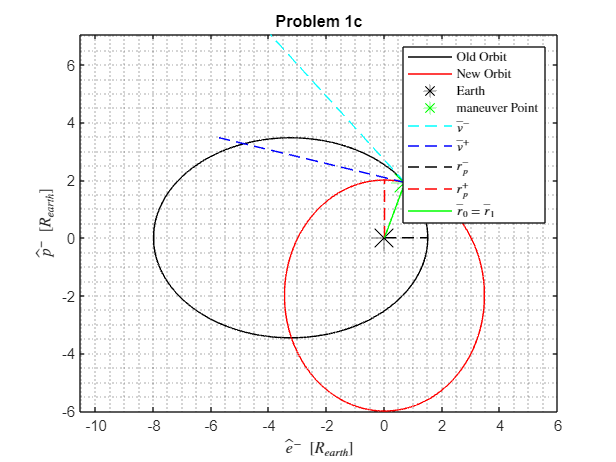

% True anomaly vector
ta_vec          = 0:.01:360;

% Initialize position vectors
r_old_Pminus    = zeros(2,length(ta_vec));   % Old orbit in original perifocal frame 
r_new_Pplus     = r_old_Pminus;              % New orbit in new perifocal frame
r_new_Pminus    = r_old_Pminus;              % New orbit in original perifocal frame

% Rotation matrix from new perifocal frame to original perifocal frame
Pminus_DCM_Pplus= [cosd(delta_AOP), -sind(delta_AOP);...
                   sind(delta_AOP), cosd(delta_AOP)];

for i = 1:length(ta_vec)

    % Calculate old orbit radii
    r_old               = p/(1 + e*cosd(ta_vec(i)));

    % Calculate new orbit radii
    r_new               = p_new/(1 + e_new*cosd(ta_vec(i)));

    % DCM matrix from rotating orbit frame to perifocal frame
    P_DCM_R             = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                           sind(ta_vec(i)), cosd(ta_vec(i))];
    
    % Rotate old orbit poisition vector from orbit frame to perifocal frame
    r_old_Pminus(:,i)   = P_DCM_R*[r_old;0];

    % Rotate new orbit poisition vector from orbit frame to perifocal frame
    r_new_Pplus(:,i)    = P_DCM_R*[r_new;0];

    % Rotate new orbit position vector from new perifocal frame to original perifocal frame
    r_new_Pminus(:,i)   = Pminus_DCM_Pplus*r_new_Pplus(:,i);

    if ta_vec(i) == round(ta,2)
        r_mp = r_old_Pminus(:,i);
    end

end

% Rotate velocity vectors into original perifocal frame
v_P         = [cosd(ta), -sind(ta);...
               sind(ta), cosd(ta)]*v_R;
v_new_P     = Pminus_DCM_Pplus*[cosd(ta_new), -sind(ta_new);...
                     sind(ta_new), cosd(ta_new)]*v_new_R;

% Rotate periapsis distance to original perifocal frame
rp_new_P    = Pminus_DCM_Pplus*[rp_new;0];

figure
plot(r_old_Pminus(1,:)/R_earth, r_old_Pminus(2,:)/R_earth,'-k')
hold on
plot(r_new_Pminus(1,:)/R_earth, r_new_Pminus(2,:)/R_earth,'-r')
plot(0, 0,'k*','MarkerSize',18)
plot(r_mp(1)/R_earth, r_mp(2)/R_earth,'g*','MarkerSize',18)
plot([r_mp(1)/R_earth r_mp(1)/R_earth+v_P(1)], [r_mp(2)/R_earth r_mp(2)/R_earth+v_P(2)],'--c')
plot([r_mp(1)/R_earth r_mp(1)/R_earth+v_new_P(1)], [r_mp(2)/R_earth r_mp(2)/R_earth+v_new_P(2)],'--b')
plot([0 rp/R_earth],[0 0],'--k')
plot([0 rp_new_P(1)/R_earth],[0 rp_new_P(2)/R_earth],'--r')
plot([0 r_mp(1)/R_earth], [0, r_mp(2)/R_earth],'-g')
grid minor
xlabel('$\hat{e}^- \  [R_{earth}]$', 'Interpreter','latex')
ylabel('$\hat{p}^- \ [R_{earth}]$', 'Interpreter','latex')
axis equal
title('Problem 1c')
legend('Old Orbit','New Orbit','Earth','maneuver Point',...
       '$\bar{v}^-$','$\bar{v}^+$','$r^-_p$','$r^+_p$','$\bar{r}_0 = \bar{r}_1$',...
       'Interpreter','latex')

function J = OrbitManeuver(x, p_new, e_new, p, e, delta_AOP)
% States
% x1 = ta_new, x2 = ta

% Equations to solve: J = 0
J(1) = p_new/(1 + e_new*cosd(x(1))) - p/(1 + e*cosd(x(2)));
J(2) = x(2) - x(1) - delta_AOP;

end